addpath("functions/");
clear

# Simulation

save_to_file = false;

L = 50;
steps = 10e2;
wait = 10e1;
N_array = [0:200:3800 4000:100:13000 13200:200:20000];
active_sites = zeros(numel(N_array),1);

model = "Manna";


j = 0;
while j < numel(N_array); j = j+1;
	N = N_array(j);
		
	eval(sprintf("%s_PBC",model));

	active_sites(j) = mean_active_sites;

end

% Cleanup workspace
clear("nn_u","nn_r", "nn_l","nn_d","d_as","l_as", ...
	"r_as","u_as","i","L_b","count","j","N","nn","t")

% Save to file if the box was checked
if save_to_file; save(sprintf('data/%s_PBC_data_%s.mat',...
		model,datestr(now,'mm-dd_HH-MM')), ...
		"active_sites","N_array","L","steps","wait","model","q","z_c"); end

# Post processing and plotting

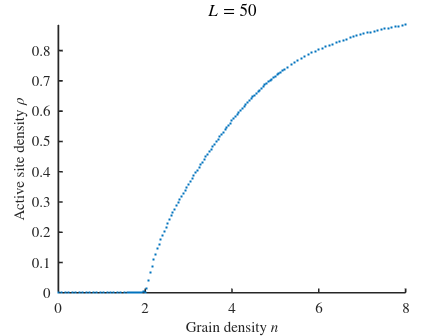

addpath("functions/");

if ~exist('active_sites','var') || ~exist('N_array','var');
	load("/home/francesco/Documents/UNI/Sistemi complessi/SOC simulation/data/BTW_PBC_data_08-23_04-13.mat"); end

title = "$L = "+L+"$";
fig = scatter_plot(N_array./L^2,active_sites./L^2,title, ...
	"Grain density $n$", "Active site density $ \rho $");